I am glad you are using my code. I will be happy to receive your feedback and help you if needed. If necessary, please contact me at habib@mm.bme.hu. If you use this software for your research, please cite my paper: Habib, G. (2021). Dynamical integrity assessment of stable equilibria: a new rapid iterative procedure. Nonlinear Dynamics, 106(3), 2073-2096

clear
% close all
% clc

Parameter values for the system and for the computation


% parameter values
par.zeta=0.05;
par.b=1;
par.a=1;
% the equation of motion is x''+2*zeta*x'-b*x+a*x^3=0

% wieght for computing the distance in the phase space. The first term
% correspond to the natural frequency squared. For more information look at
% Habib, G. (2021). Dynamical integrity assessment of stable equilibria: a 
% new rapid iterative procedure. Nonlinear Dynamics, 106(3), 2073-2096.
weight=[4 1];

% equilibrium point (or a point surely part of the basin of attraction of
% the desired equilibrium
xe0=[-1.01,0];

% variable of the phase space to be plot (unnecessary for this system,
% since it has only 1 DoF)
var1=1;
var2=2;

% number of step of the iteration
number_of_steps=50;

% space boundary
spaceboundary=[xe0-2,xe0+4];

% discretization of the phase space in each direction
discr=701;

% algorithm for choosing new initial conditions:
% 1: farthest unexplorated point in the hypersphere of convergence (usually safest but slowest)
% 2: bisection algorithm for finding trajectories on the boundary of the basin of attraction (usually highest precision)
% 3: random
type_x0=2;

Computation of the Local Integrity Measure (LIM) of the equilibrium

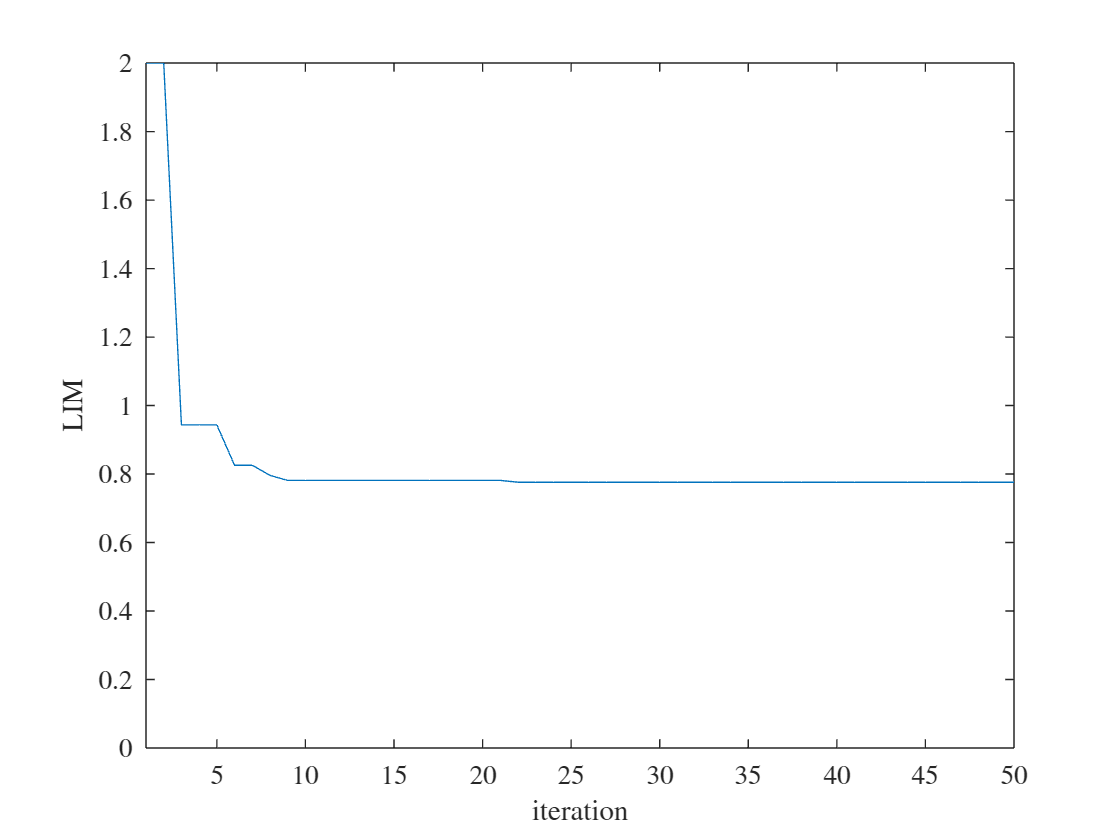

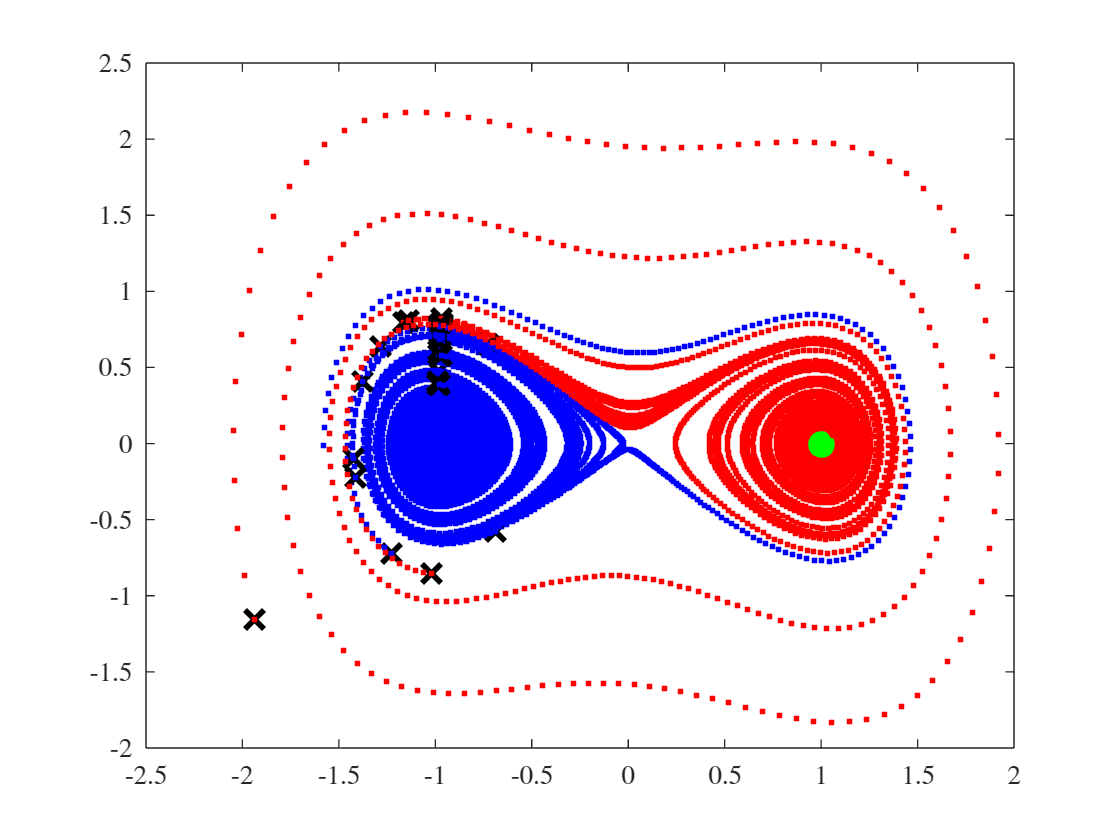

% set 'plot_results' to 0 for faster computation
[LIM,OutL,OutH]=...
    compute_LIM_FP(xe0,par,'weight',weight,'plot_results',1,'plot_results_final',0,'number_of_steps',number_of_steps,...
    'spaceboundary',spaceboundary,'discr',discr,'tfinal',2000,'num_of_cell_around_equilibrium',3,'divR',50,'num_gen',5,...
    'type_x0',type_x0,'var1',var1,'var2',var2,'check_equilibrium',1);

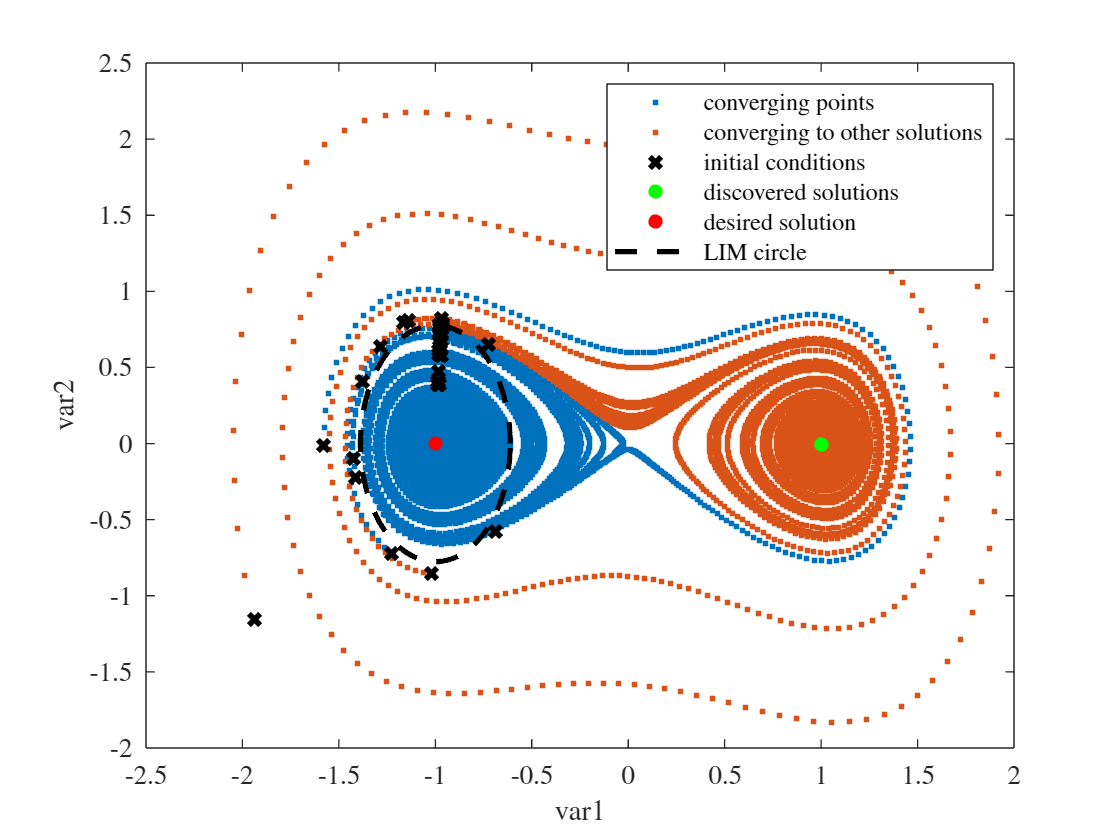


% plot the phase space with all trajectories, initial conditions 
% utilized and new steady state solutions identified
figure;
plot(OutH.vc(:,var1),OutH.vc(:,var2),'.','DisplayName','converging points');hold on;
plot(OutH.vd(:,var1),OutH.vd(:,var2),'.','DisplayName','converging to other solutions');
plot(OutH.vdout(:,var1),OutH.vdout(:,var2),'.','DisplayName','diverging points');
plot(OutL.x0(:,var1),OutL.x0(:,var2),'kx','LineWidth',2,'DisplayName','initial conditions');
xlabel('var1');ylabel('var2');
for i=1:length(OutL.other_solutions_p)
    plot(OutL.other_solutions_p{i,1}(:,var1),OutL.other_solutions_p{i,1}(:,var2),'g.','MarkerSize',16,'DisplayName','discovered solutions');
end
plot(OutL.xe(:,var1),OutL.xe(:,var2),'r.','MarkerSize',16,'DisplayName','desired solution');

% plot a circle representing the LIM
phi=linspace(0,2*pi,1000);
Rw=LIM;
dim=length(OutL.xe);
xcircW=zeros(length(phi),2);
if exist('var1','var')==0
    var1=1;
end
if exist('var2','var')==0
    var2=2;
end
for i=1:length(phi)
    for i2=1:2:dim
        xcircW(i,:)=[OutL.xe(var1)+Rw/sqrt(weight(var1))*cos(phi(i)),OutL.xe(var2)+Rw/sqrt(weight(var2))*sin(phi(i))];
    end
end
plot(xcircW(:,1),xcircW(:,2),'k--','LineWidth',2,'DisplayName','LIM circle');
legend


disp('Estimated LIM')

Estimated LIM


LIM

LIM = 0.7761

Parametric analysis. Analysis of LIM for variation of the cubic stiffness. In this part of the code, the LIM value is computed for different cubic stiffness values of the Duffing oscillator *a*.

Regarding the position of the equilibrium, which depend on *a* and changes at each step, there are two options:

1) The position of the equilibrium is computed analytically in advance and it is specified for each *a* value.

2) [NOT AVAILABLE FOR PARFOR, PARALLEL CYCLE] Use an initial value relatively close to the equilibrium point of interest and let the algorithm find the equilibrium. Then, for the next *a* value use as initial guess the equilibrium used for the previous *a* value.

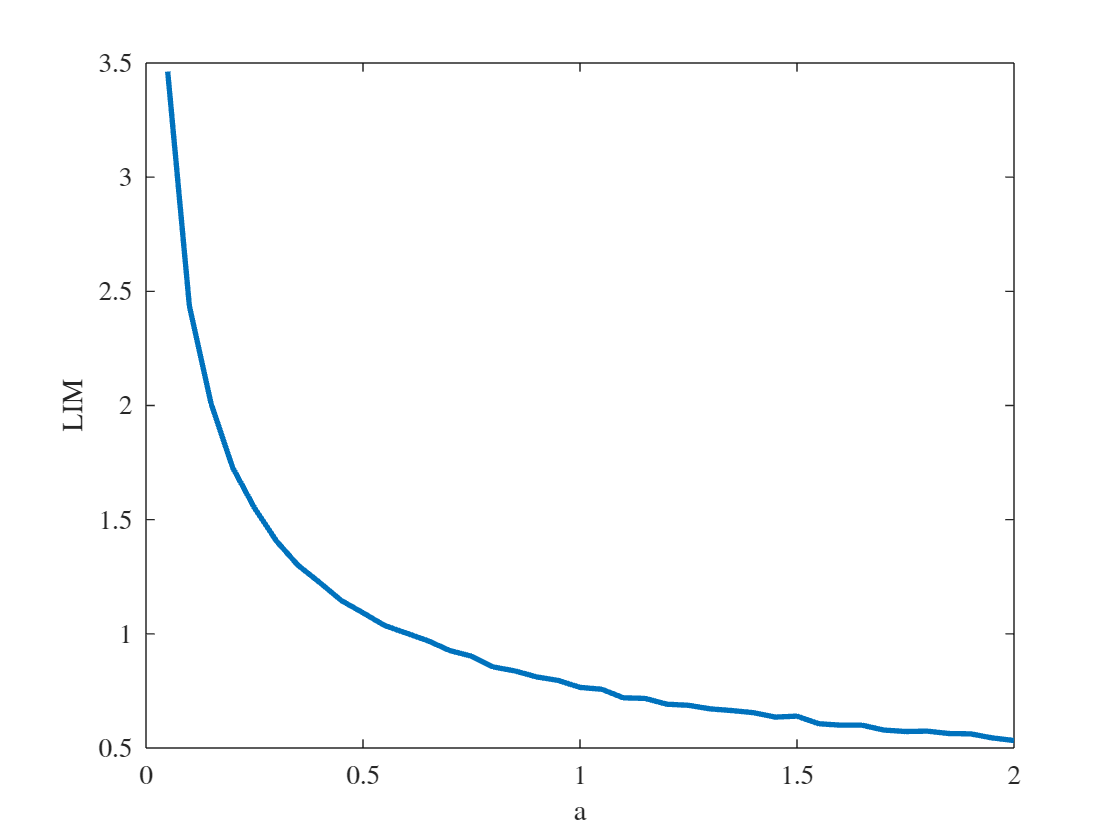

% parametric analysis. Analysis of LIM for variation of the cubic
% stiffness. In this part of the code, the LIM value is computed for
% different cubic stiffness values of the Duffing oscillator b. For each b
% value the equilibrium position must be specified.

% varying system parameter (the other parameters are those provided above)
a_v=linspace(0.05,2,40);

% computational parameters
number_of_steps=30;
discr=701;

% initialization of LIM
LIM=zeros(length(a_v),1);
temp=par; % required for using a parfor loop

% use either option 1 or option 2, they relate to two different way to make the
% parametric analysis

option = 1;

switch option

    case 1
        % option 1 for changing equiliubrium condition
        % equilibrium condition is calculated analytically and directly provided to
        % the algorithm
        % if parfor does not automatically use multiple cores, than try executing parpool before it
        % parpool
        parfor i=1:length(a_v)
            par=temp;
            par.a=a_v(i);
            xe0=[-sqrt(par.b/par.a), 0] % equilibrium changes at each iteration
            spaceboundary=[xe0-5,xe0+5] % boundaries must change depending on equilibrium
            [LIM(i)]=...
                compute_LIM_FP(xe0,par,'weight',weight,'plot_results',0,'plot_results_final',0,'number_of_steps',number_of_steps,...
                'spaceboundary',spaceboundary,'discr',discr,'tfinal',2000,'num_of_cell_around_equilibrium',3,...
                'type_x0',type_x0,'bis_iter_max',5,'var1',var1,'var2',var2);
        end

    case 2
        % option 2 for changing equiliubrium condition (equilibrium is calculated
        % by the code by using the previous equilibrium as initial guess, through
        % the command xe0=OutL.xe;
        xe0=[-sqrt(par.b/a_v(1)), 0];
        for i=1:length(a_v)
            par.a=a_v(i);
            spaceboundary=[xe0-5,xe0+5]; % boundaries must change depending on equilibrium
            [LIM(i),OutL]=...
                compute_LIM_FP(xe0,par,'weight',weight,'plot_results',0,'plot_results_final',0,'number_of_steps',number_of_steps,...
                'spaceboundary',spaceboundary,'discr',discr,'tfinal',2000,'num_of_cell_around_equilibrium',3,...
                'type_x0',type_x0,'bis_iter_max',5,'var1',var1,'var2',var2);
            xe0=OutL.xe;
        end

end
    

% visualization of the results
figure;plot(a_v,LIM,'LineWidth',2);xlabel('a');ylabel('LIM');